E.T.S. Ingeniería Informática  Grado en Ingeniería de la Salud 

Ampliación de Matemáticas  Curso 2023/24

**Nombre:**

PRÁCTICA 2. Problemas de valores inciales en ecuaciones diferenciales ordinarias. Sistemas y ecuaciones de orden superior.

Vamos ahora a modificar el fichero Pract1.mlx para resolver este otro problema también visto en clase:


$$\begin{array}{l}
\mathrm{y''}\left(t\right)=-4y\left(t\right)+4\mathrm{y'}\left(t\right),t\in \left\lbrack 0,1\right\rbrack \\
y\left(0\right)=1,\mathrm{y'}\left(0\right)=2
\end{array}$$


con solución analítica


$$y\left(t\right)=e^{2t}$$


Como en la primera parte de la práctica vamos a trabajar sobre este problema completando el estudio comenzado en clase utilizando otras técnicas numéricas.

En clase resolvimos este problema con el método de Euler explícito y comparamos con la solución analítica utillizando el siguiente código (también disponible en el fichero demoSO.m)

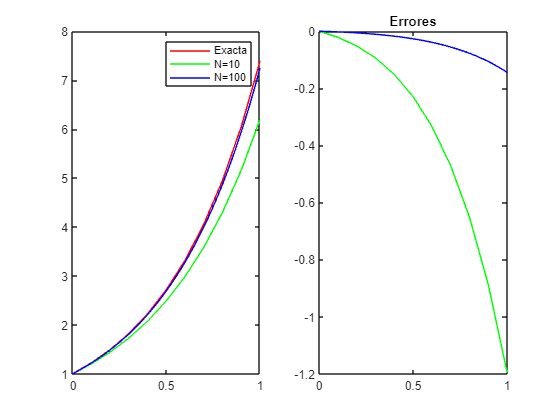

% ejemplo con ecuación de segundo orden
% y''-4y'+4y=0,y(0)=1, y'(0)=2
[y1,t1]=eulerExp(@funcSO,0,1,[1, 2],10);
z1=funcSOexacta(t1);
figure;
[y2,t2]=eulerExp(@funcSO,0,1,[1, 2],100);
z2=funcSOexacta(t2);
subplot(121);
plot(t1,z1,'r',t1,y1(:,1),'g',t2,y2(:,1),'b');
% Solo estamos utilizando la primera columna de y1 e y2 porque solo estamos interesados en la función y
% La segunda columna de estos vectores contiene la información sobre y'
legend('Exacta','N=10','N=100')
subplot(122);
plot(t1,y1(:,1)-z1','g',t2,y2(:,1)-z2','b');
title('Errores');

En esta figura se observa que al multiplicar por 10 el número de subintervalos considerados en la partición (al dividir por 10 el tamaño del paso) el error máximo al final del intervalo considerado parece que se divide por 10, lo que es característico de un método de orden de consistencia 1: el error es proporcional al tamaño del paso.

No se observa nada destacable en cuanto a la estabillidad del método. Podríamos aumentar el intervalo de tiempo en el que se calcula la solución para ver si con el tiempo se observa un comportamiento inestable.

Resuelva ahora este problema con los métodos  los métodos del punto medio, Adams-Basforth de 3 pasos  y Runge-Kutta clásico de antes y los mismos valores de N y compare los resultados obtenidos con los distintos métodos.

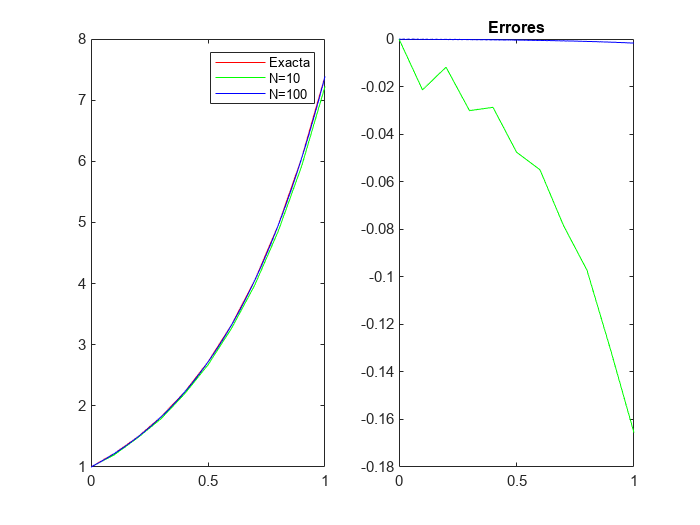

% ejemplo con ecuación de segundo orden
% y''-4y'+4y=0,y(0)=1, y'(0)=2
[g1,t1]=puntoMedio(@funcSO,0,1,[1, 2],10);
figure;
[g2,t2]=puntoMedio(@funcSO,0,1,[1, 2],100);
subplot(121);
plot(t1,z1,'r',t1,g1(:,1),'g',t2,g2(:,1),'b');
% Solo estamos utilizando la primera columna de y1 e y2 porque solo estamos interesados en la función y
% La segunda columna de estos vectores contiene la información sobre y'
legend('Exacta','N=10','N=100')
subplot(122);
plot(t1,g1(:,1)-z1','g',t2,g2(:,1)-z2','b');
title('Errores');

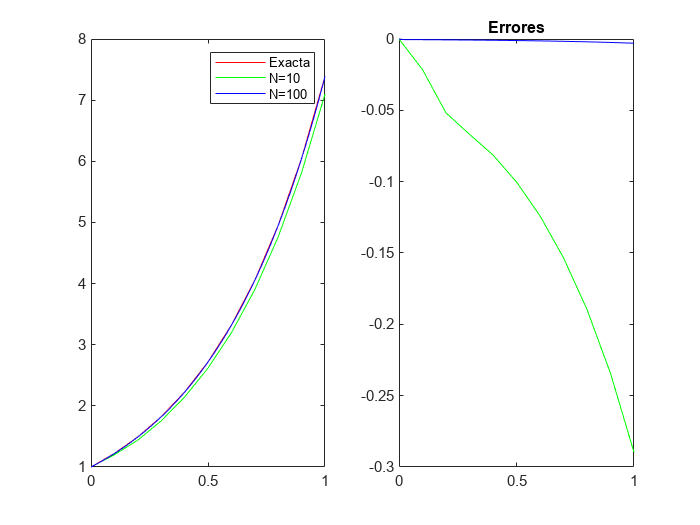

% ejemplo con ecuación de segundo orden
% y''-4y'+4y=0,y(0)=1, y'(0)=2
[l1,t1]=AB3(@funcSO,0,1,[1, 2],10);
figure;
[l2,t2]=AB3(@funcSO,0,1,[1, 2],100);
subplot(121);
plot(t1,z1,'r',t1,l1(:,1),'g',t2,l2(:,1),'b');
% Solo estamos utilizando la primera columna de y1 e y2 porque solo estamos interesados en la función y
% La segunda columna de estos vectores contiene la información sobre y'
legend('Exacta','N=10','N=100')
subplot(122);
plot(t1,l1(:,1)-z1','g',t2,l2(:,1)-z2','b');
title('Errores');

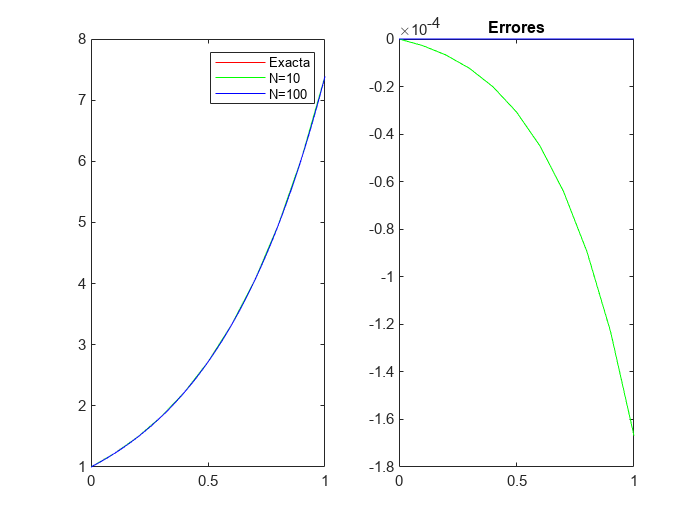

% ejemplo con ecuación de segundo orden
% y''-4y'+4y=0,y(0)=1, y'(0)=2
[n1,t1]=RK4(@funcSO,0,1,[1, 2],10);
figure;
[n2,t2]=RK4(@funcSO,0,1,[1, 2],100);
subplot(121);
plot(t1,z1,'r',t1,n1(:,1),'g',t2,n2(:,1),'b');
% Solo estamos utilizando la primera columna de y1 e y2 porque solo estamos interesados en la función y
% La segunda columna de estos vectores contiene la información sobre y'
legend('Exacta','N=10','N=100')
subplot(122);
plot(t1,n1(:,1)-z1','g',t2,n2(:,1)-z2','b');
title('Errores');

¿Qué observa en cuanto a la consistencia, convergencia y estabilidad de los métodos numéricos cuando se utilizan para resolver los problemas propuestos? Comente los resultados obtenidos. 

Se puede observar que los métodos están ordenados según su orden de convergencia ascendente, a mayor orden, más decrece el error según aumenta el número de intervalos.

También se observa que los métodos de mayor orden tienen más orden de consistencia, a excepción de Adams-Basforth que con solo 10 intervalos tiene un error más alto del que se esperaría.

# FUNCIONES DADAS

## Solución exacta del problema considerado

function y=funcSOexacta(t)
% solución analítica de y''=-4y+4y', y(0)=1, y'(0)=2
y=exp(2.*t);
end

Método de Euler explícito

function [y,t]=eulerExp(fun,a,b,alp,N);
% function [y,t]=eulerExp(fun,a,b,alp,N);
% fun puede ser el nombre de una función, p. ej. 'fun1' o un manejador
% método de Euler explícito para resolver
% y'=fun(t,y), x \in [a,b], y(a)=alp con at=(b-a)/N
at=(b-a)/N;
t=a:at:b;
[k,m]=size(alp);
y=zeros(N+1,m);
y(1,:)=alp;
for n=1:N
    y(n+1,:)=y(n,:)+at*fun(t(n),y(n,:));
end
end

Función que determina la ecuación diferencial

function f=funcSO(t,y)
% f1=y2; f2=-4y1+4y2 
% ecuación de segundo orden y''-4y'+4y=0 expresada como sistema
f(1)=y(2);
f(2)=-4.*y(1)+4.*y(2);
end


**Copia aquí las funciones que escribiste en Pract1.mlx**.

Método del punto medio  

function [y,t]=puntoMedio(fun,a,b,alp,N)
% método del punto medio para resolver
% y'=f(t,y), t \in [a,b], y(a)=alp con at=(b-a)/N
at=(b-a)/N;
t=a:at:b;
[m,n]=size(alp);
y=zeros(N+1,n);
y(1,:)=alp;
% Es necesario un método de arranque, usamos en este caso Euler Explícito
y(2,:)=y(1,:)+at*fun(t(1),y(1,:));
for i=1:N-1
    y(i+2,:)=y(i,:)+2*at*fun(t(i+1),y(i+1,:));
end
end

Método de Adams-Basforth de  tres pasos

function [y,t]=AB3(fun,a,b,alp,N)
% método de Adams-Bashforth de tercer orden para resolver
% y'=f(t,y), t \in [a,b], y(a)=alp con at=(b-a)/N
at=(b-a)/N;
t=a:at:b;
[m,n]=size(alp);
y=zeros(N+1,n);
y(1,:)=alp;
y(2,:)=y(1,:)+at*fun(t(1),y(1,:));
y(3,:)=y(2,:)+at*fun(t(2),y(2,:));
for i=1:N-2
    y(i+3,:)=y(i+2,:)+at/12*(23*fun(t(i+2),y(i+2,:))-16*fun(t(i+1),y(i+1,:))+5*fun(t(i),y(i,:)));
end
end

Método de Runge-Kutta clásico de cuarto orden  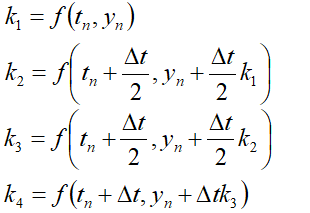

function [y,t]=RK4(fun,a,b,alp,N)
% método de Runge_kutta de cuarto orden para resolver
% y'=f(t,y), t \in [a,b], u(a)=alp con at=(b-a)/N
at=(b-a)/N;
t=a:at:b;
[m,n]=size(alp);
y=zeros(N+1,n);
y(1,:)=alp;
for i=1:N
    k1=fun(t(i),y(i,:));
    k2=fun(t(i)+at/2,y(i,:)+at/2*k1);
    k3=fun(t(i)+at/2,y(i,:)+at/2*k2);
    k4=fun(t(i)+at,y(i,:)+at*k3);
    y(i+1,:)=y(i,:)+at/6*(k1+2*k2+2*k3+k4);
end
end

¿Te siguen funcionando en este problema? Deberían funcionar si las operaciones vectoriales están bien implementadas.